## **Novo grid**

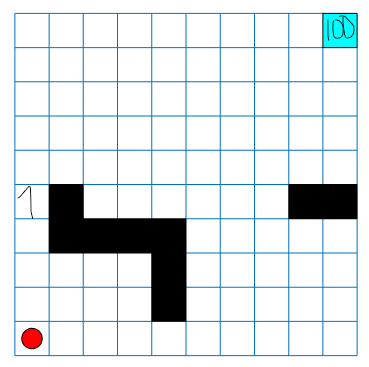

clear 

GW = createGridWorld(10,10)

GW =   GridWorld with properties:

          GridSize: [10 10]
      CurrentState: "[1,1]"
            States: [100×1 string]
           Actions: [4×1 string]
                 T: [100×100×4 double]
                 R: [100×100×4 double]
    ObstacleStates: [0×1 string]
    TerminalStates: [0×1 string]


GW.CurrentState = '[10,1]';                                                                         % posicao incial do mapa
GW.TerminalStates = '[1,10]';                                                                       % posicao terminal do mapa
GW.ObstacleStates = ["[6,2]";"[7,2]";"[7,3]";"[7,4]";"[7,5]";"[8,5]";"[9,5]";"[6,9]";"[6,10]"];     % posicoes bloqueadas

updateStateTranstionForObstacles(GW);                                                               % funcao do gridworld para bloquear as transicoes de estado a depender dos obstaculos


**define the rewards in the reward transition matrix.**

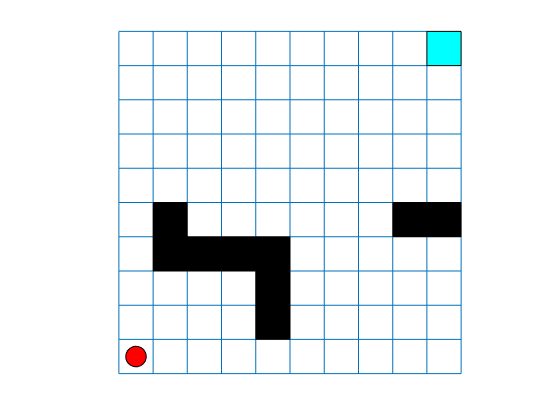

nS = numel(GW.States);
nA = numel(GW.Actions);
GW.R = -1*ones(nS,nS,nA);                                   % matrix de recompensa por transicao de estado
GW.R(state2idx(GW,"[7,1]"),state2idx(GW,"[6,1]"),1) = 1;    % https://www.mathworks.com/help/reinforcement-learning/ug/create-custom-grid-world-environments.html
GW.R(:,state2idx(GW,GW.TerminalStates),:) = 100;            % recompensa do estado terminal

env = rlMDPEnv(GW);                                         % criando o ambiente com o mapa
env.ResetFcn = @() 10;                                      % funcao de reset do ambiente
rng(0)                                                      % semente de numero aleatorio para reproducibilidade
plot(env)                                                       

disp('Tabela de recompensa do estado [7,1]');

Tabela de recompensa do estado [7,1]


for i=1:10:90
    env.Model.R(state2idx(GW,"[7,1]"),i:i+10,1)    
end

ans =     -1    -1    -1    -1    -1     1    -1    -1    -1    -1    -1


ans =     -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


ans =     -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


ans =     -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


ans =     -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


ans =     -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


ans =     -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


ans =     -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


ans =     -1    -1    -1    -1    -1    -1    -1    -1    -1    -1   100


## **Create Q-Learning Agent**

To create a Q-learning agent, first create a Q table using the observation and action specifications from the grid world environment. Set the learning rate of the representation to 1.

qTable = rlTable(getObservationInfo(env),getActionInfo(env));                                   % cria (instancia) objeto da tabela da funcao value
qRepresentation = rlQValueRepresentation(qTable,getObservationInfo(env),getActionInfo(env));    % monta representacao da funcao value com a tabela
qRepresentation.Options.LearnRate = 1;                                                          % taxa de aprendizado


Next, create a Q-learning agent using this table representation and configure the epsilon-greedy exploration. For more information on creating Q-learning agents, see [`rlQAgent`](docid:rl_ref#mw_b6721f63-a5be-47ea-9325-78f7b379ae30) and [`rlQAgentOptions`](docid:rl_ref#mw_383e9fbf-e99d-4af3-b250-49c6c4ae6f3f).

agentOpts = rlQAgentOptions;                                                                    % cria objeto de opcoes de agente
agentOpts.EpsilonGreedyExploration.Epsilon = .04;                                               % taxa de exploracao inicial em 30%
qAgent = rlQAgent(qRepresentation,agentOpts);                                                   % cria objeto agente

## **Train Q-Learning Agent**

To train the agent, first specify the training options. For this example, use the following options:

- Train for at most 200 episodes. Specify that each episode lasts for most 50 time steps.

- Stop training when the agent receives an average cumulative reward greater than 10 over 30 consecutive episodes.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

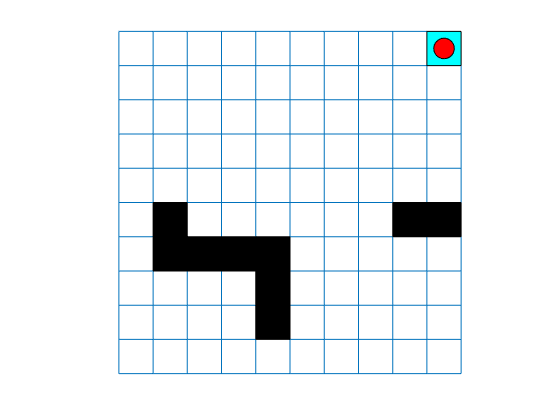

trainOpts = rlTrainingOptions;

maximaRecompensaConhecida=85;

trainOpts = rlTrainingOptions;                              % cria objeto de opcoes de treinamento                 
trainOpts.MaxStepsPerEpisode = 200;                         % maximo de 50 movimentos por episodio
trainOpts.MaxEpisodes= 1000;                                % treino por 200 episodios
%trainOpts.StopTrainingCriteria = "EpisodeReward";           % termino por recompensa do episodio
trainOpts.StopTrainingCriteria = "AverageReward";           % termino por recompensa do episodio
trainOpts.StopTrainingValue = maximaRecompensaConhecida-1;    % valor de recompensa media para termino
trainOpts.ScoreAveragingWindowLength = 30;                  % intervalo para calculo da media

%trainOpts.SaveAgentCriteria = "EpisodeReward";
%trainOpts.SaveAgentValue = maximaRecompensaConhecida;
%trainOpts.SaveAgentDirectory = "savedAgents";

trainOpts.Verbose = false;
trainOpts.Plots = "training-progress";

doTraining=true;

if doTraining
    % Train the agent.
    trainingStats = train(qAgent,env,trainOpts);
else
    load('savedAgents/GridWorldGrande/Agent312.mat','qAgent')
end

**Validate Q-Learning Results**

env.Model.CurrentState='[10,1]'

env =   rlMDPEnv with properties:

       Model: [1×1 rl.env.GridWorld]
    ResetFcn: @()10



plot(env)
env.Model.Viewer.clearTrace();

env.Model.Viewer.ShowTrace = true;
simOpts=rlSimulationOptions('MaxSteps',100)

simOpts =   rlSimulationOptions with properties:

                  MaxSteps: 100
            NumSimulations: 1
               StopOnError: "on"
               UseParallel: 0
    ParallelizationOptions: [1×1 rl.option.ParallelSimulation]


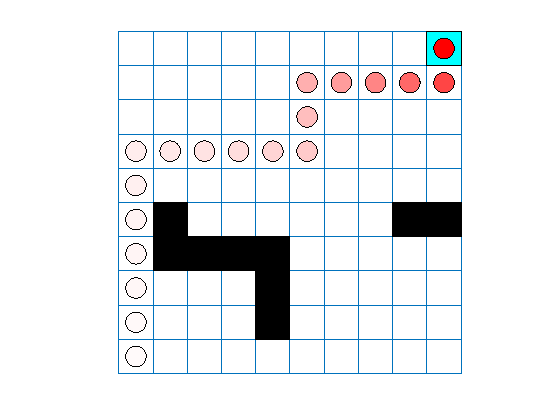

qAgent.getCritic.getValue(10,1); % vendo o valor da acao 1 a partir do estado 10

experience=sim(qAgent,env,simOpts);

experience.Reward.Data

ans =     -1
    -1
    -1
     1
    -1
    -1
    -1
    -1
    -1
    -1


**Agente espertinho**

load('savedAgents/GridWorldGrande/AgentPernaCurta.mat')
qAgent=saved_agent;
figure

env.Model.CurrentState='[10,1]'

env =   rlMDPEnv with properties:

       Model: [1×1 rl.env.GridWorld]
    ResetFcn: @()10



plot(env)
env.Model.Viewer.clearTrace();

env.Model.Viewer.ShowTrace = true;
simOpts=rlSimulationOptions('MaxSteps',100)

simOpts =   rlSimulationOptions with properties:

                  MaxSteps: 100
            NumSimulations: 1
               StopOnError: "on"
               UseParallel: 0
    ParallelizationOptions: [1×1 rl.option.ParallelSimulation]


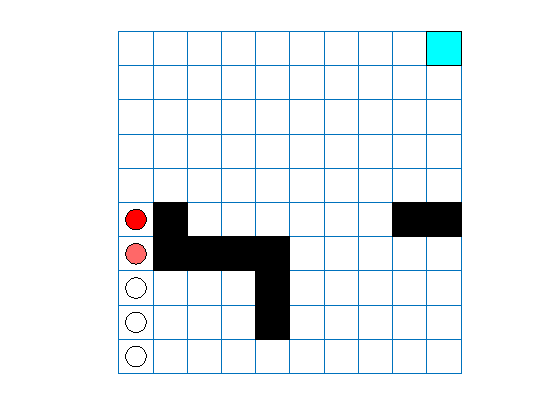


experience=sim(qAgent,env,simOpts);

experience.Reward.Data

ans =     -1
    -1
    -1
     1
    -1
     1
    -1
     1
    -1
     1


**agente medio**

load('savedAgents/GridWorldGrande/Agent980.mat')
qAgent=saved_agent;
figure

env.Model.CurrentState='[10,1]'

env =   rlMDPEnv with properties:

       Model: [1×1 rl.env.GridWorld]
    ResetFcn: @()10



plot(env)
env.Model.Viewer.clearTrace();

env.Model.Viewer.ShowTrace = true;
simOpts=rlSimulationOptions('MaxSteps',100)

simOpts =   rlSimulationOptions with properties:

                  MaxSteps: 100
            NumSimulations: 1
               StopOnError: "on"
               UseParallel: 0
    ParallelizationOptions: [1×1 rl.option.ParallelSimulation]


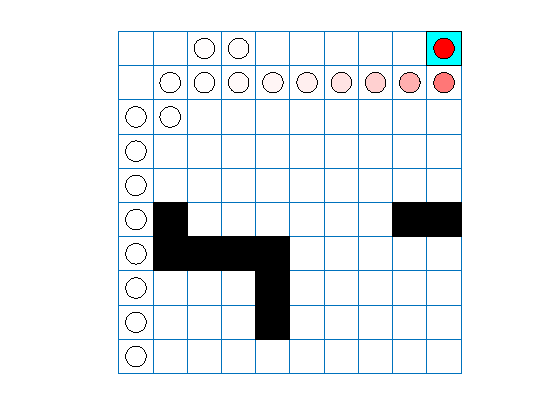


experience=sim(qAgent,env,simOpts);

experience.Reward.Data

ans =     -1
    -1
    -1
     1
    -1
    -1
    -1
    -1
    -1
    -1


**melhor agente**

load('savedAgents/GridWorldGrande/Agent312.mat')
qAgent=saved_agent;
figure

env.Model.CurrentState='[10,1]'

env =   rlMDPEnv with properties:

       Model: [1×1 rl.env.GridWorld]
    ResetFcn: @()10



plot(env)
env.Model.Viewer.clearTrace();

env.Model.Viewer.ShowTrace = true;
simOpts=rlSimulationOptions('MaxSteps',100)

simOpts =   rlSimulationOptions with properties:

                  MaxSteps: 100
            NumSimulations: 1
               StopOnError: "on"
               UseParallel: 0
    ParallelizationOptions: [1×1 rl.option.ParallelSimulation]


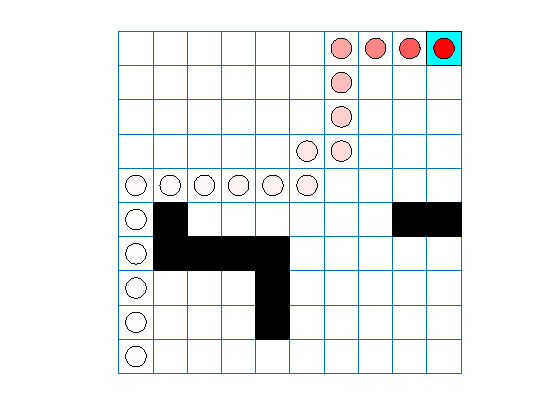


experience=sim(qAgent,env,simOpts);

experience.Reward.Data

ans =     -1
    -1
    -1
     1
    -1
    -1
    -1
    -1
    -1
    -1
